# **unsteady-state Flux Balance Analysis (FBA)**

## **James T. Yurkovich**

In this tutorial, we will use unsteady-state Flux Balance Analysis (uFBA) [1] to integrate exo- and endo-metabolomics data [2] into a constraint-based metabolic model for the human red blood cell [3]. Running this method requires the installation of a mixed-integer linear programming solver; we have used Gurobi 7.0.0 (http://www.gurobi.com/downloads/download-center) which is freely available for academic use. 

## Preliminaries

We can model the flux through a metabolic network using a set of linear equations defined by


$$\mathbf{S}\cdot \mathbf{v}=\mathbf{b}$$


where **S** is the stoichiometric matrix, **v** is a vector of fluxes through the chemical reactions defined in **S**, and **b** represents constraints on metabolite concentrations; at steady-state, **b **= 0. The first step of the uFBA workflow is to identify discrete time intervals which represent linearized metabolic states (Fig. 1). For each metabolic state, we can use linear regression to calculate the rate of change of each metabolite concentration. If the rate of change is significant, the model is updated by changing the steady-state constraint from 0 to 


$$\begin{array}{l}
\mathbf{S}\cdot \mathbf{v}\text{ }\ge {\mathbf{b}}_1 \\
\mathbf{S}\cdot \mathbf{v}\text{ }\le {\mathbf{b}}_2 
\end{array}$$


where [$\mathbf{b}_1$, $\mathbf{b}_2$] represents the 95% confidence interval for each significantly changing metabolite. All unmeasured metabolites are assumed to be at steady-state (i.e., $\mathbf{b}_1 = \mathbf{b}_2 = 0$).

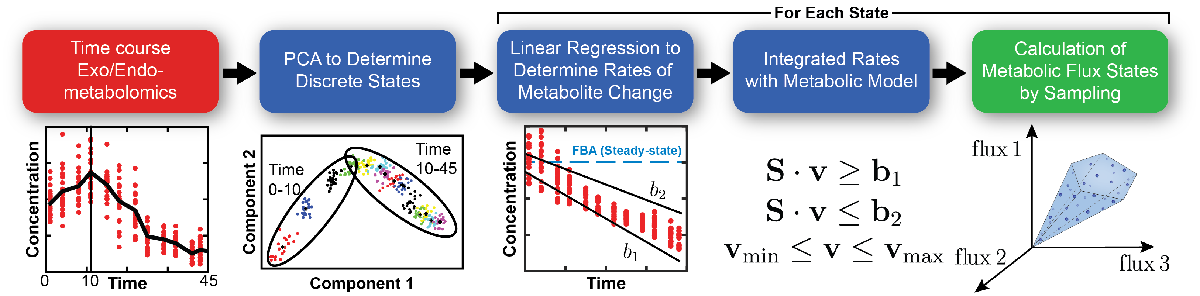

                                                    Fig. 1 | Overview of the uFBA workflow.

## Example 

initCobraToolbox()

LP solver set to gurobi5 successful
MILP solver set to gurobi5 successful
QP solver set to gurobi5 successful
MIQP solver set to gurobi5 successful
CB map output set to svg successful


We first load in the data. This data is absolutely quantified and has already been volume adjusted such that intracellular and extracellular metabolite concentrations have compatible units. 

load sample_data;

changeCobraSolver('gurobi7', 'LP');

changeCobraSolver('gurobi7', 'MILP');

The `sample_data.mat` file contains the following variabels:

- `met_data`: a matrix containing the exo- and endo-metabolomics data

- `met_IDs`: a cell array containing the BiGG ID for each of the metabolites in `met_data`

- `model`: a modified version [3] of the iAB-RBC-283 COBRA model structure

- `time`: a vector of the time points (in days) at which the metabolite concentrations were measured

- `uFBAvariables`: a struct containing the variables necessary for input into the uFBA algorithm

Next, we run linear regression to find the rate of change for each metabolite concentration.

changeSlopes = zeros(length(met_IDs), 1);
changeIntervals = zeros(length(met_IDs), 1);
for i = 1:length(met_IDs)
    [tmp1, tmp2] = regress(met_data(:, i), [time ones(length(time), 1)], 0.05);
    changeSlopes(i, 1) = tmp1(1);
    changeIntervals(i, 1) = abs(changeSlopes(i, 1) - tmp2(1));
end

The variables `changeSlopes` and `changeIntervals` contain the metabolite rates of change and 95% confidence intervals, respectively. We will create a new vector, `ignoreSlopes`, which contains a `1` for the metabolites whose slopes change significantly and a `0` otherwise:

tmp1 = changeSlopes - changeIntervals;
tmp2 = changeSlopes + changeIntervals;
ignoreSlopes = double(tmp1 < 0 & tmp2 > 0);

Finally, we need to input the data into the uFBA algorithm which is encapsulated in the function `buildUFBAmodel`. This function takes as input a COBRA model structure and a struct containing the required input variables (see Table 1).

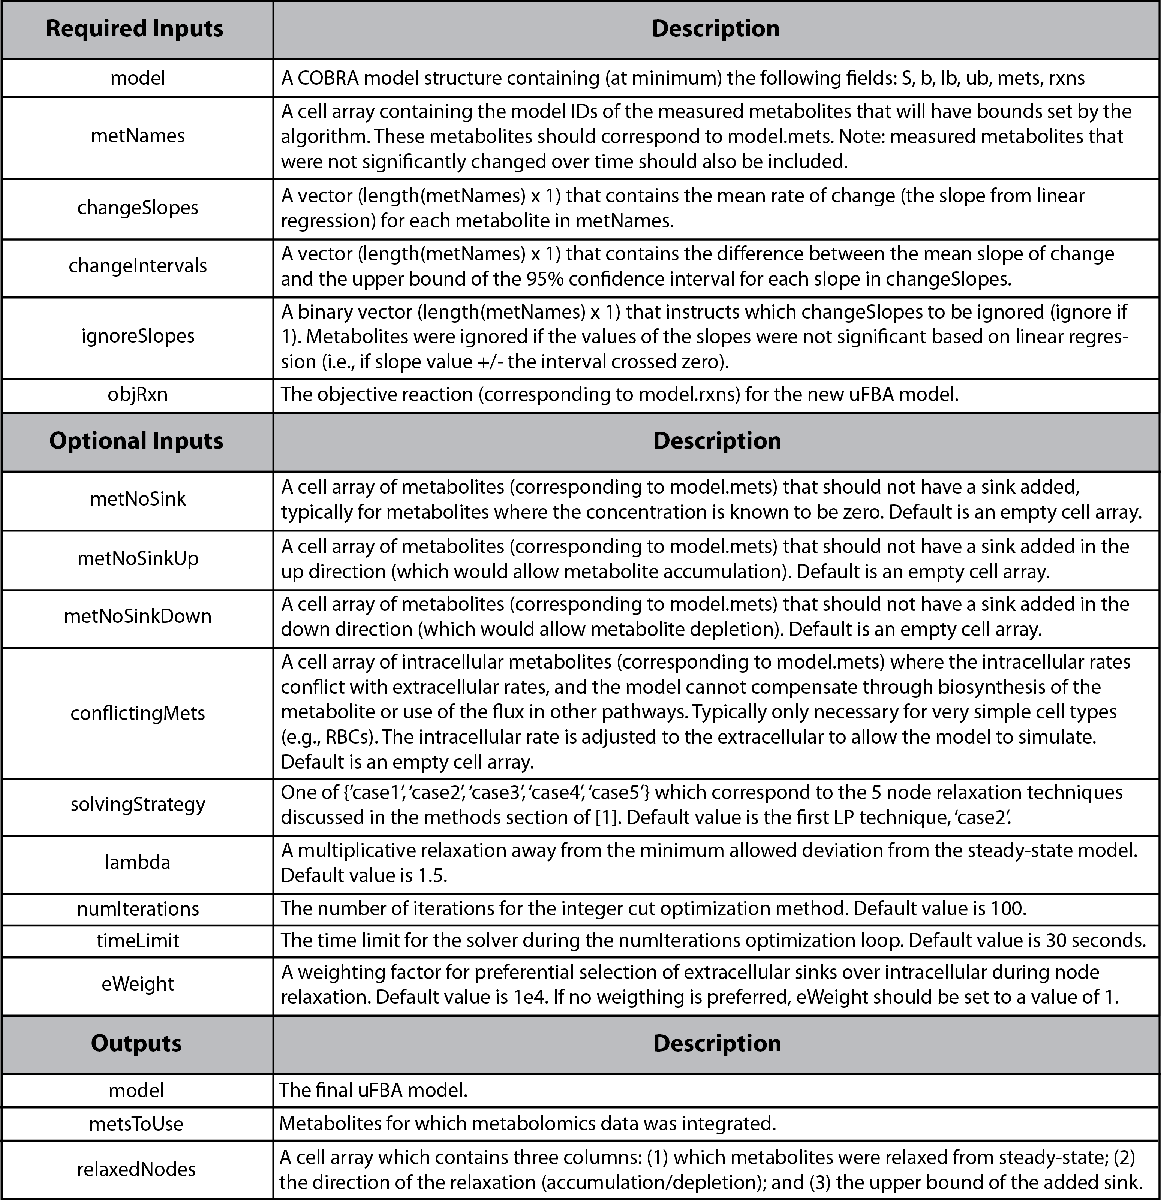

                                       Table 1 | Inputs and outputs of the `buildUFBAmodel` function.

uFBAvariables.metNames = met_IDs;
uFBAvariables.changeSlopes = changeSlopes;
uFBAvariables.changeIntervals = changeIntervals;
uFBAvariables.ignoreSlopes = ignoreSlopes;

uFBAoutput = buildUFBAmodel(model, uFBAvariables);

sink_ascb-L[c]	ascb-L[c] 	<=>	
sink_gthrd[e]	gthrd[e] 	<=>	
sink_urate[e]	urate[e] 	<=>	
In addReaction, the class of systNameList is doublesink_10fthf[c]_up	10fthf[c]_G + 10fthf[c]_L 	=>	
In addReaction, the class of systNameList is doublesink_13dpg[c]_up	13dpg[c]_G + 13dpg[c]_L 	=>	
In addReaction, the class of systNameList is doublesink_2kmb[c]_up	2kmb[c]_G + 2kmb[c]_L 	=>	
In addReaction, the class of systNameList is doublesink_35cgmp[c]_up	35cgmp[c]_G + 35cgmp[c]_L 	=>	
In addReaction, the class of systNameList is doublesink_35cgmp[e]_up	35cgmp[e]_G + 35cgmp[e]_L 	=>	
In addReaction, the class of systNameList is doublesink_5mdr1p[c]_up	5mdr1p[c]_G + 5mdr1p[c]_L 	=>	
In addReaction, the class of systNameList is doublesink_5mdru1p[c]_up	5mdru1p[c]_G + 5mdru1p[c]_L 	=>	
In addReaction, the class of systNameList is doublesink_6pgl[c]_up	6pgl[c]_G + 6pgl[c]_L 	=>	
In addReaction, the class of systNameList is doublesink_ac[c]_up	ac[c]_G + ac[c]_L 	=>	
In addReaction, the class of systNa

The resulting model (`uFBAoutput.model`) can be converted back to a steady-state COBRA model (i.e., $\mathbf{S \cdot v} = 0$) using the function `ufba2fba` so that standard COBRA methods can be used:

model_ufba = ufba2fba(uFBAoutput.model);

sink_23dpg[c]		<=>	23dpg[c] 
sink_2pg[c]		<=>	2pg[c] 
sink_3pg[c]		<=>	3pg[c] 
sink_5mta[c]	5mta[c] 	<=>	
sink_5oxpro[c]	5oxpro[c] 	<=>	
sink_6pgc[c]		<=>	6pgc[c] 
sink_ade[c]		<=>	ade[c] 
sink_adp[c]		<=>	adp[c] 
sink_ahcys[c]	ahcys[c] 	<=>	
sink_ala-L[c]	ala-L[c] 	<=>	
sink_amet[c]	amet[c] 	<=>	
sink_amp[c]		<=>	amp[c] 
sink_arg-L[c]		<=>	arg-L[c] 


sink_asn-L[c]		<=>	asn-L[c] 
sink_atp[c]	atp[c] 	<=>	
sink_cit[c]		<=>	cit[c] 
sink_f6p[c]	f6p[c] 	<=>	
sink_fdp[c]		<=>	fdp[c] 
sink_g6p[c]	g6p[c] 	<=>	
sink_glu-L[c]		<=>	glu-L[c] 
sink_gmp[c]		<=>	gmp[c] 
sink_gthox[c]	gthox[c] 	<=>	
sink_gthrd[c]		<=>	gthrd[c] 
sink_his-L[c]		<=>	his-L[c] 
sink_ile-L[c]		<=>	ile-L[c] 
sink_imp[c]	imp[c] 	<=>	
sink_ins[c]		<=>	ins[c] 
sink_lac-L[c]	lac-L[c] 	<=>	
sink_lys-L[c]		<=>	lys-L[c] 
sink_mal-L[c]		<=>	mal-L[c] 
sink_mnl[c]	mnl[c] 	<=>	
sink_pep[c]		<=>	pep[c] 
sink_phe-L[c]		<=>	phe-L[c] 
sink_r5p[c]		<=>	r5p[c] 
sink_ru5p-D[c]		<=>	ru5p-D[c] 
sink_ser-L[c]		<=>	ser-L[c] 
sink_trp-L[c]		<=>	trp-L[c] 
sink_tyr-L[c]		<=>	tyr-L[c] 
sink_udpg[c]		<=>	udpg[c] 
sink_urate[c]		<=>	urate[c] 
sink_uri[c]	uri[c] 	<=>	
sink_val-L[c]		<=>	val-L[c] 
sink_xan[c]	xan[c] 	<=>	
sink_xu5p-D[c]		<=>	xu5p-D[c] 
In addReaction, the class of systNameList is doubleEX_5oxpro(e)	5oxpro[e] 	=>	
In addReaction, the class of systNameList is doubleEX_ade(e)	ade[e] 	=>	

sol = optimizeCbModel(model_ufba)

ans =            x: [295×1 double]
           f: 0.2296
           y: [215×1 double]
           w: [295×1 double]
        stat: 1
    origStat: 'OPTIMAL'
      solver: 'gurobi5'
        time: 0.0026


## References

[1] A Bordbar*, JT Yurkovich*, G Paglia, O Rolfsson, O Sigurjonsson, and BO Palsson. "Elucidating dynamic metabolic physiology through network integration of quantitative time-course metabolomics." *Scientific Reports *(2017). doi:10.1038/srep46249. (* denotes equal contribution)

[2] A Bordbar, PI Johansson, G Paglia, SJ Harrison, K Wichuk, M Magnusdottir, S Valgeirsdottir, M Gybel-Brask, SR Ostrowski, S Palsson, O Rolfsson, OE Sigurjonsson, MB Hansen, S Gudmundsson, and BO Palsson. "Identified metabolic signature for assessing red blood cell unit quality is associated with endothelial damage markers and clinical outcomes." *Transfusion* (2016). doi:10.1111/trf.13460.

[3] A Bordbar, D McCloskey, DC Zielinski, N Sonnenschein, N Jamshidi, and BO Palsson. "Personalized Whole-Cell Kinetic Models of Metabolism for Discovery in Genomics and Pharmacodynamics." *Cell Systems* (2015). doi:10.1016/j.cels.2015.10.003.